clear; clc; close all;

## Variable definition

% Nominal Component Values
R1_nom = 30e3; % R1 nominal value in ohms
R2_nom = 18e3; % R2 nominal value in ohms
C1_nom = 0.01e-6; % C1 nominal value in farads
C2_nom = 0.0047e-6; % C2 nominal value in farads

% Tolerance
tol = 0.05;

% Bounds for component based on tolerance
R1_lower = R1_nom * (1 - tol);   R1_upper = R1_nom * (1 + tol);
R2_lower = R2_nom * (1 - tol);   R2_upper = R2_nom * (1 + tol);
C1_lower = C1_nom * (1 - tol);   C1_upper = C1_nom * (1 + tol);
C2_lower = C2_nom * (1 - tol);   C2_upper = C2_nom * (1 + tol);

% Simulation parameters
N = 10000; % Number of Monte Carlo samples

% Array for storing |Vout|
Vout_samples = zeros(N,1);

## Section 2: Monte Carlo Simulation Loop

for i = 1:N
    % Randomly sample components from uniform distribution
    R1_sample = R1_lower + (R1_upper - R1_lower) * rand();
    R2_sample = R2_lower + (R2_upper - R2_lower) * rand();
    C1_sample = C1_lower + (C1_upper - C1_lower) * rand();
    C2_sample = C2_lower + (C2_upper - C2_lower) * rand();

    % Evaluate output using Sallen-Key simulation function
    Vout = simulate_sallenKeyFilter(R1_sample, R2_sample, C1_sample, C2_sample);

    % Store the magnitude of Vout
    Vout_samples(i) = abs(Vout);
end

## Section 3: Statistical analysis

% Basic information
mean_Vout = mean(Vout_samples);
std_Vout  = std(Vout_samples);
variance_Vout = var(Vout_samples);
median_Vout = median(Vout_samples);
min_Vout = min(Vout_samples);
max_Vout = max(Vout_samples);

% Percentiles (5th, 25th, 50th, 75th, 95th)
percentiles = prctile(Vout_samples, [5 25 50 75 95]);

% Skewness
skewness_Vout = skewness(Vout_samples);

% Kurtosis
kurtosis_Vout = kurtosis(Vout_samples);

% 95% Confidence Interval for the Mean
alpha = 0.05;
z = norminv(1 - alpha/2);  % Two-tailed (1.96 for 95% CI)
CI_lower = mean_Vout - z * std_Vout/sqrt(N);
CI_upper = mean_Vout + z * std_Vout/sqrt(N);

% Errors
StandardError = std_Vout / sqrt(N);
RelativeErrorPercent = (StandardError / mean_Vout) * 100;

## Display the computed statistics

fprintf('\nMonte Carlo Simulation Results (N = %d samples):\n', N);


Monte Carlo Simulation Results (N = 10000 samples):


fprintf('---------------------------------------------\n');

---------------------------------------------


fprintf('Mean of |Vout|                 : %.4f V\n', mean_Vout);

Mean of |Vout|                 : 0.7060 V


fprintf('Standard Deviation of |Vout|    : %.4f V\n', std_Vout);

Standard Deviation of |Vout|    : 0.0255 V


fprintf('Variance of |Vout|              : %.4f V^2\n', variance_Vout);

Variance of |Vout|              : 0.0006 V^2


fprintf('Median of |Vout|                : %.4f V\n', median_Vout);

Median of |Vout|                : 0.7056 V


fprintf('Minimum of |Vout|              : %.4f V\n', min_Vout);

Minimum of |Vout|              : 0.6382 V


fprintf('Maximum of |Vout|              : %.4f V\n', max_Vout);

Maximum of |Vout|              : 0.7730 V


fprintf('5th Percentile                 : %.4f V\n', percentiles(1));

5th Percentile                 : 0.6648 V


fprintf('25th Percentile                : %.4f V\n', percentiles(2));

25th Percentile                : 0.6873 V


fprintf('50th Percentile (Median)       : %.4f V\n', percentiles(3));

50th Percentile (Median)       : 0.7056 V


fprintf('75th Percentile                : %.4f V\n', percentiles(4));

75th Percentile                : 0.7250 V


fprintf('95th Percentile                : %.4f V\n', percentiles(5));

95th Percentile                : 0.7481 V


fprintf('Skewness                       : %.4f\n', skewness_Vout);

Skewness                       : 0.0329


fprintf('Kurtosis                       : %.4f\n', kurtosis_Vout);

Kurtosis                       : 2.3926


fprintf('95%% Confidence Interval for Mean: [%.4f, %.4f] V\n', CI_lower, CI_upper);

95% Confidence Interval for Mean: [0.7055, 0.7065] V


fprintf('Standard Error of the Mean     : %.4f V\n', StandardError);

Standard Error of the Mean     : 0.0003 V


fprintf('Relative Error (%%)             : %.2f%%\n', RelativeErrorPercent);

Relative Error (%)             : 0.04%


## Section 4: Plots

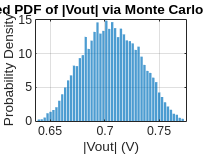

% Estimated PDF
nbins = 50;
[counts, binCenters] = hist(Vout_samples, nbins);
pdf_Vout = counts / trapz(binCenters, counts);

figure;
bar(binCenters, pdf_Vout, 'FaceAlpha', 0.7, 'EdgeColor', 'none');
xlabel('|Vout| (V)');
ylabel('Probability Density');
title('Estimated PDF of |Vout| via Monte Carlo Simulation');
grid on;

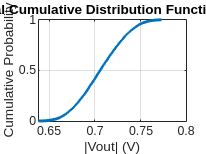


% Empirical Cumulative Distribution Function (ECDF)
figure;
[f_ecdf, x_ecdf] = ecdf(Vout_samples);
stairs(x_ecdf, f_ecdf, 'LineWidth', 2);
xlabel('|Vout| (V)');
ylabel('Cumulative Probability');
title('Empirical Cumulative Distribution Function of |Vout|');
grid on;

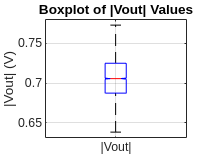


% Boxplot for data spread
figure;
boxplot(Vout_samples, 'Notch','on', 'Labels', {'|Vout|'});
ylabel('|Vout| (V)');
title('Boxplot of |Vout| Values');
grid on;

## **Section 5: PCE model for sallen key surrogate model fitting**

### **Sample from sallen key**


N_samples = 20000;

R1_nominal = 30e3;
R1_min = 0.95 * R1_nominal;
R1_max = 1.05 * R1_nominal;

R2_nominal = 18e3;
R2_min = 0.95 * R2_nominal;
R2_max = 1.05 * R2_nominal;

C1_nominal = 0.01e-6;
C1_min = 0.95 * C1_nominal;
C1_max = 1.05 * C1_nominal;

C2_nominal = 0.0047e-6;
C2_min = 0.95 * C2_nominal;
C2_max = 1.05 * C2_nominal;

R1_samples = unifrnd(R1_min, R1_max, [N_samples, 1]);
R2_samples = unifrnd(R2_min, R2_max, [N_samples, 1]);
C1_samples = unifrnd(C1_min, C1_max, [N_samples, 1]);
C2_samples = unifrnd(C2_min, C2_max, [N_samples, 1]);

Vout = zeros(N_samples, 1);

for i = 1:N_samples
    Vout(i) = simulate_sallenKeyFilter(R1_samples(i), R2_samples(i), C1_samples(i), C2_samples(i));
end

Vout = abs(Vout) % we only care about the magnitude

Vout =     0.6833
    0.6820
    0.7308
    0.6944
    0.7458
    0.7046
    0.7178
    0.6593
    0.6804
    0.7420


### Normalize to [-1, 1] - range for Legendre domain


function X_norm = normalize_to_legendre(X, X_min, X_max)
    X_norm = 2 * (X - X_min) ./ (X_max - X_min) - 1;
end

R1_samples_norm = normalize_to_legendre(R1_samples, R1_min, R1_max);
R2_samples_norm = normalize_to_legendre(R2_samples, R2_min, R2_max);
C1_samples_norm = normalize_to_legendre(C1_samples, C1_min, C1_max);
C2_samples_norm = normalize_to_legendre(C2_samples, C2_min, C2_max);

X_norm = [R1_samples_norm, R2_samples_norm, C1_samples_norm, C2_samples_norm]; % (N, 4)

X_train = X_norm(1:10000, :);
X_test = X_norm(10001:end, :);

y_train = Vout(1:10000);
y_test = Vout(10001:end, :);

### Create PCE model

#### First, generate multi-indices for all interaction terms and polynomial orders

function alpha = generate_multi_indices(d, p)
    alpha = [];
    for total = 0:p
        temp = nchoosek(repmat(0:total, 1, d), d);
        temp = unique(temp(sum(temp, 2) == total, :), 'rows');
        alpha = [alpha; temp];
    end
end

d = size(X_norm, 2); % number of parameters in our circuit
p = 3; % max Legendre polynomial order

alpha = generate_multi_indices(d, p)

alpha =      0     0     0     0
     0     0     0     1
     0     0     1     0
     0     1     0     0
     1     0     0     0
     0     0     0     2
     0     0     1     1
     0     0     2     0
     0     1     0     1
     0     1     1     0


#### Then, we create a function to evaluate the Legendre polynomials. Technically we could use something like Rodrigue's method to evaluate them, but since we won't really ever use p > 3, we can just write down the first 4 Legendre basis functions and evaluate them directly.

function P = eval_legendre(n, x)
    
    psi = {
        @(x) ones(size(x));         % Psi_0 = 1
        @(x) x;                     % Psi_1 = x
        @(x) 0.5 * (3*x.^2 - 1);    % Psi_2 = 1/2 * (3x^2 - 1)
        @(x) 0.5 * (5*x.^3 - 3*x);  % Psi_3 = 1/2 * (5x^3 - 3x)
    };

    if n < 0 || n > 3
        error('Not currently in range... Add more terms to the hardcoded basis');
    end

    P = psi{n+1}(x);
end

eval_legendre(0, X_norm(:, 1))

ans =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


#### Now we can create the basis matrix which will contain the value of all the Legendre basis functions for each sample. This matrix can then be used with least squares to find the coefficients for best fit.

function Psi = eval_basis_matrix(X, alpha)

    [N, d] = size(X); % N the number of samples and d, the dimensionality - the number of parameters
    P = size(alpha, 1); % number of basis functions (function of the max order of polynomial and number of interaction term given by number of parameters)

    Psi = ones(N, P); % for each sample, the value of all the basis functions evaluated at that sample. The surrogate model is a linear combination of these terms.

    for i = 1:P
        tmp_psi = ones(N, 1);
        for j = 1:d % for each parameter (allows for interaction terms)
            tmp_psi = tmp_psi .* eval_legendre(alpha(i, j), X(:, j));
        end
        Psi(:, i) = tmp_psi;
    end
end

Psi_train = eval_basis_matrix(X_train, alpha)

Psi_train =     1.0000    0.9410    0.3652   -0.9107    0.0965    0.8282    0.3437   -0.2999   -0.8570   -0.3326    0.7442    0.0908    0.0352   -0.0879   -0.4860    0.6716    0.3025   -0.2822   -0.4260   -0.7543   -0.3130    0.2731    0.7003    0.2718   -0.5225    0.0799    0.0332   -0.0289   -0.0827   -0.0321    0.0718   -0.4574   -0.1775    0.4427   -0.1425
    1.0000    0.2892    0.0704   -0.5303    0.9383   -0.3746    0.0204   -0.4926   -0.1533   -0.0373   -0.0781    0.2713    0.0660   -0.4976    0.8205   -0.3733   -0.0264   -0.1424   -0.1047    0.1987   -0.0108    0.2612   -0.0226   -0.0055    0.4226   -0.3515    0.0191   -0.4622   -0.1439   -0.0350   -0.0733    0.2372    0.0578   -0.4351    0.6575
    1.0000   -0.3017   -0.6051   -0.5828   -0.3512   -0.3635    0.1825    0.0491    0.1758    0.3526    0.0095    0.1060    0.2125    0.2047   -0.3150    0.3839    0.2199   -0.0148    0.3538    0.2118   -0.1064   -0.0286   -0.0029   -0.0057    0.3793    0.1277   -0.0641   -0.0173   -0.

Psi_test = eval_basis_matrix(X_test, alpha)

Psi_test =     1.0000   -0.8611   -0.3077   -0.4953    0.7138    0.6123    0.2650   -0.3580    0.4265    0.1524   -0.1320   -0.6147   -0.2197   -0.3536    0.2644   -0.3047   -0.1884    0.3083    0.3887   -0.3033   -0.1313    0.1773    0.1136    0.0406    0.4392    0.4371    0.1892   -0.2555    0.3045    0.1088   -0.0942   -0.2276   -0.0813   -0.1309   -0.1614
    1.0000    0.3433   -0.8131   -0.9371   -0.1628   -0.3232   -0.2792    0.4917   -0.3217    0.7620    0.8173   -0.0559    0.1324    0.1525   -0.4603   -0.4138    0.2628    0.1688   -0.1243    0.3029    0.2616   -0.4608    0.2806   -0.6646   -0.6518    0.0526    0.0454   -0.0800    0.0524   -0.1240   -0.1330   -0.1580    0.3742    0.4313    0.2334
    1.0000    0.3908   -0.2034   -0.3897    0.3958   -0.2709   -0.0795   -0.4380   -0.1523    0.0793   -0.2721    0.1547   -0.0805   -0.1542   -0.2651   -0.4370    0.0551   -0.1712    0.2840    0.1056    0.0310    0.1707   -0.1064    0.0553    0.4366   -0.1072   -0.0315   -0.1733   -0.0

#### Now that we have the matrix Psi with all the values of the basis functions, we want to find a linear combination that approximates Vout as well as possible. We will use least squares to do that.

For least squares, we would find the coefficients by doing 

$a={\left(\Psi^T \Psi \right)}^{-1} \Psi^T y$, which would be equivalent to using the matlab built-in \ operator.

% fit the surrogate model 
a = Psi_train \ y_train

a =     0.7058
   -0.0353
    0.0000
   -0.0132
   -0.0220
    0.0009
   -0.0009
   -0.0003
   -0.0002
   -0.0009


a = inv(Psi_train' * Psi_train) * (Psi_train' * y_train)

a =     0.7058
   -0.0353
    0.0000
   -0.0132
   -0.0220
    0.0009
   -0.0009
   -0.0003
   -0.0002
   -0.0009



y_hat_train = Psi_train * a;
mean_res_err_train = mean(abs(y_train - y_hat_train))

mean_res_err_train = 1.4050e-06

rel_err_train = 100 * norm(y_train - y_hat_train) / norm(y_train)

rel_err_train = 3.0915e-04

### Evaluate PCE model

#### Errors and PDFs

y_hat_test = Psi_test * a;
mean_res_err_test = mean(abs(y_test - y_hat_test))

mean_res_err_test = 1.4403e-06

rel_err_test = 100 * norm(y_test - y_hat_test) / norm(y_test)

rel_err_test = 3.2380e-04

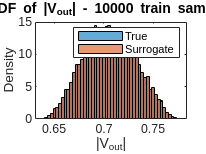


% plot pdf of monte carlo vs surrogate
figure;
histogram(y_test, 50, 'Normalization', 'pdf');
hold on;
histogram(y_hat_test, 50, 'Normalization', 'pdf');
legend('True', 'Surrogate');
title('PDF of |V_{out}| - 10000 train samples');
xlabel('|V_{out}|');
ylabel('Density');

#### Plot error in mean and std predictions over training set size.

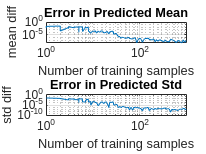

function [mean_errors, std_errors] = mean_std_err_over_train_size(X_all, y_all, alpha, X_test, y_test, sample_sizes)
    
    n_sizes = length(sample_sizes);
    mean_errors = zeros(n_sizes, 1);
    std_errors = zeros(n_sizes, 1);

    Psi_test = eval_basis_matrix(X_test, alpha); % precompute test basis matrix (doesn't change)

    for k = 1:n_sizes
        n_train = sample_sizes(k);

        % select random subset
        idx = randperm(size(X_all, 1), n_train);
        X_train = X_all(idx, :);
        y_train = y_all(idx);

        % get basis matrix for train set
        Psi_train = eval_basis_matrix(X_train, alpha);

        a = Psi_train \ y_train;
        y_hat_test = Psi_test * a;

        % get errors
        mean_errors(k) = abs(mean(y_hat_test) - mean(y_test));
        std_errors(k)  = abs(std(y_hat_test) - std(y_test));
    end
end

sample_sizes = round(logspace(log10(1), log10(1000), 100)); % 1000 samples from 1, to 1000
[mean_errors, std_errors] = mean_std_err_over_train_size(X_train, y_train, alpha, X_test, y_test, sample_sizes);

% plot results
figure

subplot(2,1,1);
loglog(sample_sizes, mean_errors);
title('Error in Predicted Mean');
xlabel('Number of training samples');
ylabel('mean diff');
grid on;

subplot(2,1,2);
loglog(sample_sizes, std_errors);
title('Error in Predicted Std');
xlabel('Number of training samples');
ylabel('std diff');
grid on;

#### Plot PDF with surrogate trained on "only" 100 samples

% fit the surrogate model 
a = Psi_train(1:20, :) \ y_train(1:20)

a =     0.7058
   -0.0352
   -0.0000
   -0.0132
   -0.0220
    0.0009
   -0.0008
   -0.0003
         0
   -0.0010



y_hat_train = Psi_train * a;
mean_res_err_train = mean(abs(y_train - y_hat_train))

mean_res_err_train = 1.0437e-04

rel_err_train = 100 * norm(y_train - y_hat_train) / norm(y_train)

rel_err_train = 0.0206


y_hat_test = Psi_test * a;
mean_res_err_test = mean(abs(y_test - y_hat_test))

mean_res_err_test = 1.0468e-04

rel_err_test = 100 * norm(y_test - y_hat_test) / norm(y_test)

rel_err_test = 0.0208

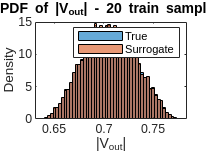


% plot pdf of monte carlo vs surrogate
figure;
histogram(y_test, 50, 'Normalization', 'pdf');
hold on;
histogram(y_hat_test, 50, 'Normalization', 'pdf');
legend('True', 'Surrogate');
title('PDF of |V_{out}| - 20 train samples');
xlabel('|V_{out}|');
ylabel('Density');